clc,clear

# 线性系统直接法

A=[1,1,1;2,5,-1;3,1,2];
b=[6;4;10];
x=gaussianElimination(A,b);

误差:  ||A*x-b||=8.88e-16

fprintf(['解为：',num2str(x')])

解为：-0.22222      1.7778      4.4444

A=[2,3,-1;4,4,-3;-2,2,4];
b=[1;5;6];
x=LuFactorization(A,b);

误差:  ||A*x-b||=0.00e+00

fprintf(['解为：',num2str(x')])

解为：39 -16  29

A=[4,2,2;2,5,2;2,2,9];
x=choleskyFactorization(A,b);

误差:  ||A*x-b||=9.16e-16

fprintf(['解为：',num2str(x')])

解为：-0.52419     0.98387     0.56452

# 线性系统迭代法

A=[4,-1,0,0,0;
    -1,4,-1,0,0;
    0,-1,4,-1,0;
    0,0,-1,4,-5;
    0,0,0,-1,4];
b=[2;4;6;8;16];
x0=zeros(5,1);
iter_max=100;
tol=1e-8;
[x,~,~,error_his1]=jacobiIteration(A,b,iter_max,tol,x0);

误差小于:1.00e-08
退出循环
总迭代次数为46


disp(['最终解为：',num2str(x')])

最终解为：1.14388      2.57554      5.15827      12.0576      7.01439


[x,~,~,error_his2]=gaussSeidelIteration(A,b,iter_max,tol,x0);

w=1 <=> Gauss-Seidel method
w=1.000000
误差小于:1.00e-08
退出循环
总迭代次数为25


disp(['最终解为：',num2str(x')])

最终解为：1.14388      2.57554      5.15827      12.0576      7.01439


w=[1.25,1.5,1.75];
error_his3=zeros(100,3);
for index=1:length(w)
    [x,~,~,error_his]=SORIteration(A,b,iter_max,tol,x0,w(index));
    error_his3(1:length(error_his),index)=error_his;
    disp(['最终解为：',num2str(x')])
end

w=1.250000
误差小于:1.00e-08
退出循环
总迭代次数为18


最终解为：1.14388      2.57554      5.15827      12.0576      7.01439


w=1.500000
误差小于:1.00e-08
退出循环
总迭代次数为34


最终解为：1.14388      2.57554      5.15827      12.0576      7.01439


w=1.750000
误差小于:1.00e-08
退出循环
总迭代次数为79


最终解为：1.14388      2.57554      5.15827      12.0576      7.01439


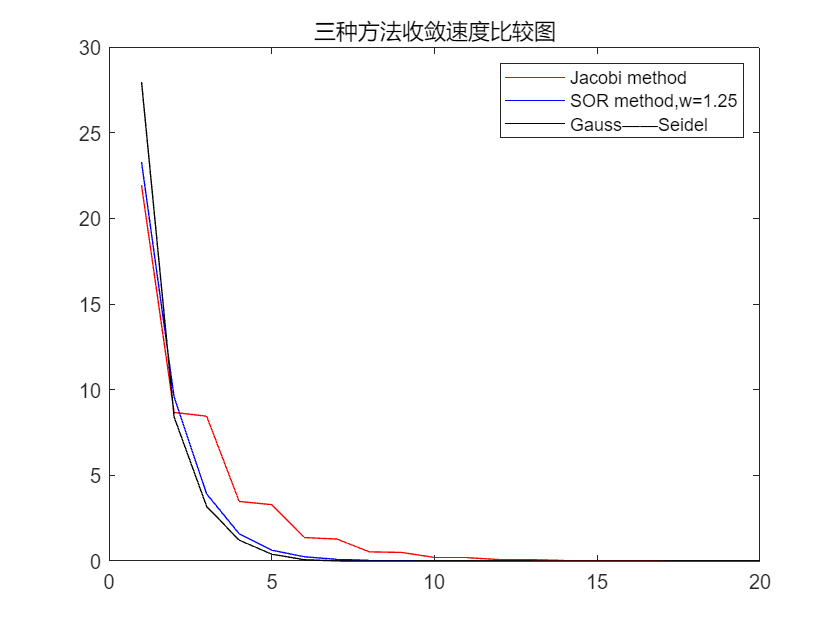

plot(1:length(error_his1),error_his1,'r-',1:length(error_his2),error_his2,'b-',1:length(error_his3(:,1)),error_his3(:,1),'k-')
legend('Jacobi method','SOR method,w=1.25','Gauss——Seidel')
xlim([0,20])
title('三种方法收敛速度比较图')
hold off

# 求根法 

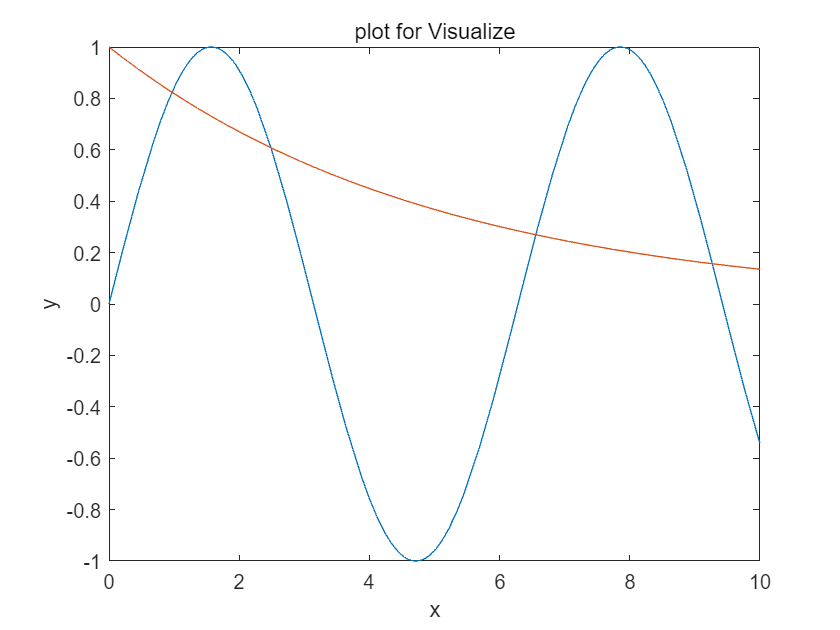

clc,clear
close all
fplot(@(x)sin(x),[0,10]);
hold on
fplot(@(x)exp(-x/5), [0, 10])
title('plot for Visualize')
xlabel('x')
ylabel('y')
hold off

--------------
第1个解：


二分法


总迭代次数为24


解为：0.968320

牛顿法


误差小于容差,退出循环,误差||abs(func(x))||为：5.32e-12
func(x)=5.32e-12
总迭代次数为3


解为：0.968320

简化牛顿法


误差小于容差,退出循环,误差||abs(func(x))||为：3.53e-09
总迭代次数为6


解为：0.968320

--------------
第2个解：


二分法


总迭代次数为26


解为：2.488081

牛顿法


误差小于容差,退出循环,误差||abs(func(x))||为：1.35e-09
func(x)=1.35e-09
总迭代次数为2


解为：2.488081

简化牛顿法


误差小于容差,退出循环,误差||abs(func(x))||为：5.31e-09
总迭代次数为3


解为：2.488081

--------------
第3个解：


二分法


总迭代次数为27


解为：6.556052

牛顿法


误差小于容差,退出循环,误差||abs(func(x))||为：2.78e-16
func(x)=-2.78e-16
总迭代次数为3


解为：6.556052

简化牛顿法


误差小于容差,退出循环,误差||abs(func(x))||为：9.83e-10
总迭代次数为4


解为：6.556052

--------------
第4个解：


二分法


总迭代次数为27


解为：9.267440

牛顿法


误差小于容差,退出循环,误差||abs(func(x))||为：7.49e-16
func(x)=-7.49e-16
总迭代次数为3


解为：9.267440

简化牛顿法


误差小于容差,退出循环,误差||abs(func(x))||为：1.32e-09
总迭代次数为4


解为：9.267440

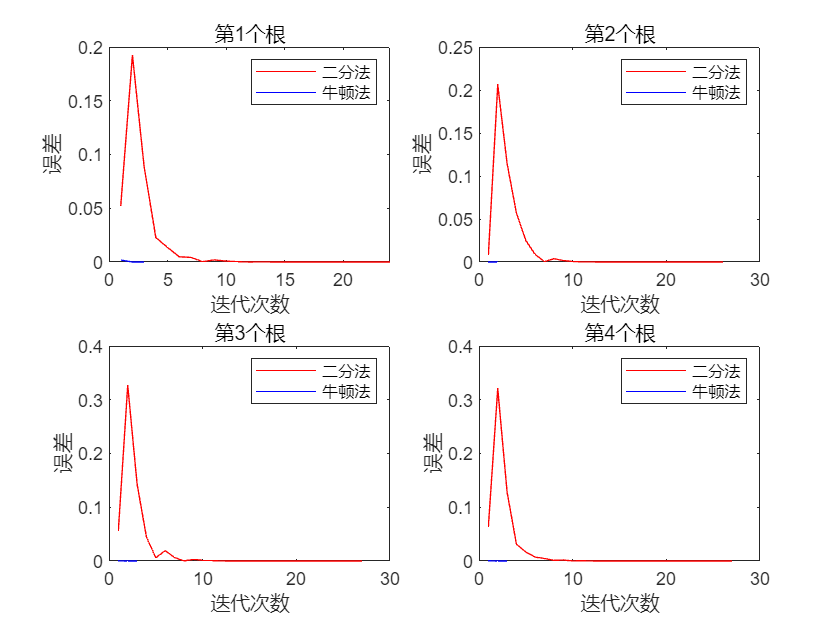

clc,clear,close all
func=@(z)exp(-z/5)-sin(z);
x0=[0.9,2.5,6.5,9.2];
iter_max=100;
tol=1e-8;
for nums=1:4
    fprintf('--------------\n第%d个解：\n',nums)
    disp('二分法')
    [x,~,~,error_his1]=Bisection(func,iter_max,tol,[x0(nums)-0.8,x0(nums)+0.8]);
    fprintf('解为：%f',x)
    disp('牛顿法')
    [x,~,~,error_his2]=Newtown(func,iter_max,tol,x0(nums));
    fprintf('解为：%f',x)
    disp('简化牛顿法')
    [x,~,~,~]=Simple_Newtown(func,iter_max,tol,x0(nums));
    fprintf('解为：%f',x)
    subplot(2,2,nums)
    plot(1:length(error_his1),error_his1,'r-',1:length(error_his2),error_his2,'b-')
    t=num2str(nums);
    xlabel('迭代次数')
    ylabel('误差')
    t=['第',t,'个根'];
    title(t)
    legend('二分法','牛顿法')
    hold on
end

##  牛顿法 vs 简化牛顿法

func=@(z)(z-3)^4*sin(z);
x0=2;
iter_max=1e+7;
disp('牛顿法')

牛顿法


[x,~,~,error_his2]=Newtown(func,iter_max,tol,x0);

误差小于容差,退出循环,误差||abs(func(x))||为：4.05e-09
func(x)=4.05e-09
总迭代次数为17


fprintf('解为：%f',x)

解为：2.987260

disp('简化牛顿法')

简化牛顿法


[x,~,~,error_his3]=Simple_Newtown(func,iter_max,tol,x0);

误差小于容差,退出循环,误差||abs(func(x))||为：1.00e-08
总迭代次数为2053793


fprintf('解为：%f',x)

解为：2.984109

# 4 插值

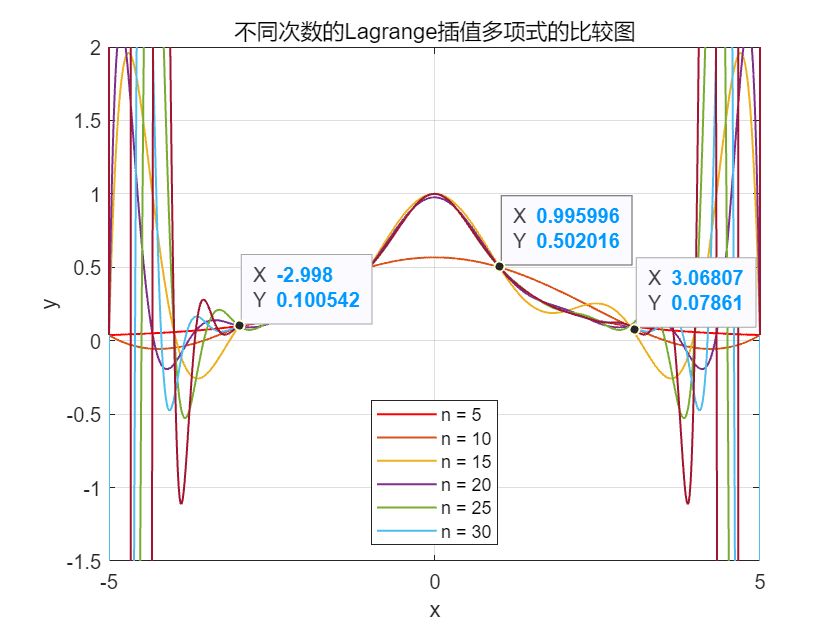

clc,clear
close all
f=@(x)1./(1+x.^2);
x=linspace(-5,5,1000);
n=5:5:30;
y=f(x);
plot(x,y,'r-',LineWidth=1)
xlabel('x')
ylabel('y')
title("不同次数的Lagrange插值多项式的比较图")
set(gca,"XGrid","on","YGrid","on")
ylim([-1.5,2])
legend('Real')
hold on
for i=1:length(n)
    X=linspace(-5,5,n(i)+1);
    Y=f(X);
    y=LagrangeInterp(X,Y,n(i),x);
    plot(x,y,LineWidth=1);
    legendInfo{i} = sprintf('n = %d', n(i));
    hold on 
end
legend(legendInfo, 'Location', 'south')
hold off 

ax = gca;
chart = ax.Children(1);
datatip(chart,0.996,0.502);
datatip(chart,3.068,0.07861);
datatip(chart,-2.998,0.1005);

function x = gaussianElimination(A, b)
% 高斯消元法求解线性方程组 Ax = b。
% 输入参数：
%   A: 系数矩阵
%   b: 右侧常数向量
% 输出参数：
%   x: 解向量
A_=A;
b_=b;
n = size(A, 1);
A = [A, b];
for i = 1:n-1
    [~, max_row] = max(abs(A(i:n, i)));
    max_row = max_row + i - 1;
    A([i, max_row], :) = A([max_row, i], :);   
    for j = i+1:n
        factor = A(j, i) / A(i, i);
        A(j, i:n+1) = A(j, i:n+1) - factor * A(i, i:n+1);
    end
end
x = zeros(n, 1);
x(n) = A(n, n+1) / A(n, n);
for i = n-1:-1:1
    x(i) = (A(i, n+1) - A(i, i+1:n) * x(i+1:n)) / A(i, i);
end
error=A_*x-b_;
fprintf('误差:  ||A*x-b||=%.2e',norm(error))
end

function x=LuFactorization(A,b)
    [L,U]=LU(A);
    [n,~]=size(A);
    A_=A;
    b_=b;
    y=ones(n,1)*b(1);
    for i=2:n
        y(i)=b(i)-L(i,1:i-1)*y(1:i-1);
    end
    x=y/U(n,n);
    for i=n-1:-1:1
        x(i)=(y(i)-U(i,i+1:n)*x(i+1:n))/U(i,i);
    end
    error=A_*x-b_;
    fprintf('误差:  ||A*x-b||=%.2e',norm(error))
end
function [L,U]=LU(A)
    [n,m]=size(A);
    if m~=n
        fprintf('\nError:A不是方阵！\n')
        return
    end
    L=eye(n);
    U=zeros(n);
    U(1,:)=A(1,:);
    L(2:end,1)=A(2:end,1)/U(1,1);
    for k=2:n
        for j=k:n
            U(k,j)=A(k,j)-L(k,1:k-1)*U(1:k-1,j);
        end
        for j=k:n
            L(j,k)=(A(j,k)-L(j,1:k-1)*U(1:k-1,k))/U(k,k);
        end
    end
end
function x=choleskyFactorization(A,b)
L=Cholesky(A);
n=size(A,1);
x=zeros(n,1);
A_=A;
b_=b;
if L==0
    fprintf('ERROR:矩阵A无法进行Cholesky分解\n')
    return
else
    U=L';
    y=ones(n,1)*b(1)/L(1,1);
    for i=2:n
        y(i)=(b(i)-L(i,1:i-1)*y(1:i-1))/L(i,i);
    end
    x=y/L(n,n);
    for i=n-1:-1:1
        x(i)=(y(i)-U(i,i+1:n)*x(i+1:n))/L(i,i);
    end
    error=A_*x-b_;
    fprintf('误差:  ||A*x-b||=%.2e',norm(error))
end
end
function L=Cholesky(A)
[n,~]=size(A);

L=zeros(n);
if isPDM(A)==false
    fprintf('ERROR:该矩阵不是对称正定矩阵\n')
    return
else
    for i=1:n
        if i==1
            L(1,1)=sqrt(A(1,1));
        else
            L(i,i)=sqrt(A(i,i)-sum(L(1:i-1,i).^2));
        end
        for j=i+1:n
            L(i,j)=(A(i,j)-sum((L(1:i-1,i).*L(1:i-1,j))))/L(i,i);
        end
    end   
end
L=L';
end
function flag=isPDM(X)
[n,m]=size(X);
flag=true;
if n~=m
    flag=false;
    fprintf('ERROR:该矩阵不是方阵\n')
    return
else
    eigenvalues = eig(X);
    if any(eigenvalues <= 0)
        flag=false;
        fprintf('ERROR:该矩阵不是正定矩阵\n')
    end
    flag3=true;
    for i=1:n
        for j=1:n
            if X(i,j)~=X(j,i)
                flag3=false;
            end
        end
    end
    if flag3==false
        flag=flag3;
        fprintf('ERROR:该矩阵不是对称矩阵\n')
    end
end
end

function [x,Error,x_his,error_his]=jacobiIteration(A,b,iter_max,tol,x0)
% Jacobi 迭代方法求解线性方程组 Ax=b。
% 输入参数：
%   A: 系数矩阵
%   b: 右侧常数向量
%   iter_max: 最大迭代次数（可选，默认为100）
%   tol: 收敛容差（可选，默认为1e-8）
%   x0: 初始解向量（可选，默认为全零向量）
% 输出参数：
%   x: 求解得到的解向量
%   Error: 每次迭代的误差
%   x_his: 每次迭代得到的解向量历史记录
%   error_his: 每次迭代的误差历史记录
[~,n]=size(A);
D=zeros(n);
if isempty(iter_max)
    iter_max=100;
end
if isempty(tol)
    tol=1e-8;
end
if nargin==5
    x=x0;
else
    x=zeros(n,1);
end
x_his=x'.*ones(iter_max,n); %以行的形式存储解
error_his=zeros(iter_max,1);
iter_num=1;
for i=1:n
     D(i,i)=A(i,i);
end
while iter_num<iter_max
    temp=x;
    for k=1:n        
        x(k)=(-A(k,:)*temp+A(k,k)*temp(k)+b(k))/A(k,k);
    end
    x_his(iter_num,:)=x;
    Error=norm(A*x-b);
    %fprintf('iter_num= %d Error=%.2e\n',iter_num,Error)
    error_his(iter_num)=Error;
    if Error<=tol
        fprintf('误差小于:%.2e\n退出循环\n',tol)
        error_his=error_his(1:iter_num);
        x_his=x_his(1:iter_num,:);
        break;        
    end
    iter_num=iter_num+1;    
end
if iter_num==iter_max
    fprintf('达到最大迭代次数，误差为：%.2e\n',error_his(end))
end
fprintf('总迭代次数为%d\n',iter_num)
end
function [x,Error,x_his,error_his]=gaussSeidelIteration(A,b,iter_max,tol,x0)
% 输入参数：
%   A: 系数矩阵
%   b: 右侧常数向量
%   iter_max: 最大迭代次数（可选，默认为100）
%   tol: 收敛容差（可选，默认为1e-8）
%   x0: 初始解向量（可选，默认为全零向量）
% 输出参数：
%   x: 求解得到的解向量
%   Error: 每次迭代的误差
%   x_his: 每次迭代得到的解向量历史记录
%   error_his: 每次迭代的误差历史记录
    w=1;
    [x,Error,x_his,error_his]=SORIteration(A,b,iter_max,tol,x0,w);
end
function [x,Error,x_his,error_his]=SORIteration(A,b,iter_max,tol,x0,w)
% SOR (Successive Over-Relaxation) 方法求解线性方程组 Ax=b。
% 输入参数：
%   A: 系数矩阵
%   b: 右侧常数向量
%   w: 松弛因子（可选，默认为1.3）
%   iter_max: 最大迭代次数（可选，默认为100）
%   tol: 收敛容差（可选，默认为1e-8）
%   x0: 初始解向量（可选，默认为全零向量）
% 输出参数：
%   x: 求解得到的解向量
%   Error: 每次迭代的误差
%   x_his: 每次迭代得到的解向量历史记录
%   error_his: 每次迭代的误差历史记录
%   w=1 为Gauss-Seidel
    
    [~,n]=size(A); 
    error_his=zeros(iter_max,1);
    iter_num=1;
    if nargin<3
        iter_max=100;
    end
    if nargin<4
        tol=1e-8;
    end
    if nargin<5
        x0=zeros(n,1);
        x=x0;
    else
        x=x0;
    end
    if nargin<6
        w=1.3;
         fprintf('松弛因子w=1.3\n')
    elseif nargin==6
        if w==1
            fprintf('w=1 <=> Gauss-Seidel method\n')
        end
    end
    fprintf('w=%f\n',w) 
    if isempty(x0)
        x=zeros(n,1);
    end
    x_his=x'.*ones(iter_max,n); %以行的形式存储
    x_pre=x;
    x_hat=x;
    while iter_num<iter_max        
        for k=1:n        
            x_hat(k)=(-A(k,:)*x+A(k,k)*x(k)+b(k))/A(k,k);
            x(k)=(1-w)*x_pre(k)+w*x_hat(k);
        end
        x_his(iter_num,:)=x';
        Error=norm(A*x-b);
        %fprintf('iter_num= %d Error=%.2e\n',iter_num,Error)
        error_his(iter_num)=Error;
        if Error<=tol
            fprintf('误差小于:%.2e\n退出循环\n',tol)
            error_his=error_his(1:iter_num);
            x_his=x_his(1:iter_num,:);
            break;        
        end
        x_pre=x;
        iter_num=iter_num+1;    
    end
    if iter_num==iter_max
        fprintf('达到最大迭代次数，误差为：%.2e\n',error_his(end))
    end
    fprintf('总迭代次数为%d\n',iter_num)
end

function [x,error,x_his,error_his]=Bisection(func,iter_max,tol,bounds)
% Bisection 函数使用二分法来求解给定函数在指定区间上的根。
% 输入参数:
%   func: 待求解的函数句柄或符号表达式。
%   iter_max (可选): 最大迭代次数，默认为 100。
%   tol (可选): 误差容限，默认为 1e-8。
%   bounds: 包含上下界的一维数组，用于指定求解区间。
%
% 输出参数:
%   x: 近似根的值。
%   error: 近似根的误差。
%   x_his: 迭代过程中的根的历史记录。
%   error_his: 迭代过程中根的误差的历史记录。
    if isempty(iter_max)
        iter_max=100;
    end
    if isempty(tol)
        tol=1e-8;
    end
    a=bounds(1);b=bounds(2);
    fa=func(a);fb=func(b);
    iter_num=1;
    x_his=ones(iter_max,1);
    error_his=zeros(iter_max,1);
    while iter_num<iter_max
        x=(a+b)/2;
        x_his(iter_num)=x;
        fx=func(x);
        %fprintf('iter_num=%d,a/fa=%.4f/%.4f,x/fx=%.4f/%.4f,b/fb=%.4f/%.4f',iter_num,a,fa,x,fx,b,fb)
        fprintf('\n')
        error=abs(func(x));
        error_his(iter_num)=error;
        if error<tol
            %fprintf('误差小于容差,退出循环,误差上限为：%.2e\n',error)
            error_his=error_his(1:iter_num);
            x_his=x_his(1:iter_num,:);
            break;
        end
        if fx*fa<0
            fb=fx;b=x;
        elseif fx*fb<0
            a=x;fa=fx;
        else 
            fprintf('func(a)*func(b)>0')
            break
        end
        if fa==0
            x=a;
            break  
        elseif fb==0
            x=b;
            break
        end
        iter_num=iter_num+1;
    end
    if iter_max==iter_num
        fprintf('达到最大迭代次数退出循环,误差上限为：%.2e\n',error)
    end
    fprintf('总迭代次数为%d\n',iter_num)
end
function [x,error,x_his,error_his]=Newtown(func,iter_max,tol,x0)
% Newtown 函数使用牛顿法来求解给定函数的根。 
% 输入参数:
%   func: 待求解的函数句柄或符号表达式。 传入的函数符号应为 z
%   iter_max (可选): 最大迭代次数，默认为 100。
%   tol (可选): 误差容限，默认为 1e-8。
%   x0 (可选): 初始值，默认为随机生成的大于 1 的数。
%
% 输出参数:
%   x: 近似根的值。
%   error: 近似根的误差。
%   x_his: 迭代过程中的根的历史记录。
%   error_his: 迭代过程中根的误差的历史记录。
   syms z
   f=sym(func);
   df=diff(f,z);
   df=matlabFunction(df);
   if isempty(iter_max)
        iter_max=100;
    end
    if isempty(tol)
        tol=1e-8;
    end
    if nargin<4
        x0=rand+1;
        x=x0;
        fprintf('未输入初始值,随机初始化x0=%f\n',x)
    else
        x=x0;
    end
    x_his=ones(iter_max,1);
    error_his=zeros(iter_max,1);
    iter_num=1;
    while iter_num<iter_max
        x0=x;
        x=x0-func(x)/df(x);
        x_his(iter_num)=x;
        error=abs(func(x));
        error_his(iter_num)=error;
        %fprintf('iter_num= %d Error=%.2e\n',iter_num,error)
        if error<tol
            fprintf('误差小于容差,退出循环,误差||abs(func(x))||为：%.2e\n',error)
            fprintf('func(x)=%.2e\n',func(x))
            error_his=error_his(1:iter_num);
            x_his=x_his(1:iter_num,:);
            break;
        end
        iter_num=iter_num+1;
    end
    if iter_max==iter_num
        fprintf('达到最大迭代次数退出循环,误差||abs(func(x))||为：%.2e\n',error)
    end
    fprintf('总迭代次数为%d\n',iter_num)
end

function  [x,error,x_his,error_his]=Simple_Newtown(func,iter_max,tol,x0,df)
    % 输入参数：
    %   - func：非线性方程的函数句柄或字符串表示形式。函数 func 应接受一个标量输入 x，并返回该点的函数值。
    %   - iter_max：最大迭代次数（可选）。默认值为 100。
    %   - tol：收敛容差（可选）。默认值为 1e-8。
    %   - x0：初始点（可选）。默认值为一个随机数加 1。
    %   - df：函数 func 的导数（可选）。可以是函数句柄或字符串表示形式。如果未提供导数，将通过符号计算自动计算导数。
    %
    % 输出参数：
    %   - x：近似的根。
    %   - error：近似根与上一次迭代的差的范数。
    %   - x_his：每次迭代的根的历史记录。
    %   - error_his：每次迭代的误差的历史记录。
    %
    % tips：
    %   - 当输入参数 iter_max 或 tol 为空时，使用默认值。
    %   - 如果未提供初始点 x0，则随机生成一个初始点。
    %   - 如果未提供导数 df，则使用符号计算自动计算导数。
   if isempty(iter_max)
        iter_max=100;
    end
    if isempty(tol)
        tol=1e-8;
    end
    if nargin<4
        x0=rand+1;
        x=x0;
        fprintf('未输入初始值,随机初始化x0=%f\n',x)
    else
        x=x0;
    end
    if nargin<5 
       syms z
       f=sym(func);
       df=diff(f,z);
       df=matlabFunction(df);
       df=df(x0);
    end
    x_his=ones(iter_max,1);
    error_his=zeros(iter_max,1);
    iter_num=1;
    while iter_num<iter_max
        x0=x;
        x=x0-func(x)/df;
        x_his(iter_num)=x;
        error=abs(func(x));
        error_his(iter_num)=error;
        %fprintf('iter_num= %d Error=%.2e\n',iter_num,error)
        if error<tol
            fprintf('误差小于容差,退出循环,误差||abs(func(x))||为：%.2e\n',error)
            error_his=error_his(1:iter_num);
            x_his=x_his(1:iter_num,:);
            break;
        end
        iter_num=iter_num+1;
    end
    if iter_max==iter_num
        fprintf('达到最大迭代次数退出循环,误差||abs(func(x))||为：%.2e\n',error)
    end
    fprintf('总迭代次数为%d\n',iter_num)
end

function y = LagrangeInterp(X,Y,n,x)
%% Larange Interpolation 
% 输入： X 插值点
%       Y 插值点函数值
%       n 插值次数
%       x 逼近点
%       y 逼近值
    if n >= length(X)
        fprintf('错误：插值点不够\n');
        return
    end    
    m = length(x);
    y = zeros(m,1);
    for k = 0 : n
        for i = 1:m
         y(i) = y(i) + Y(k+1)*prod(x(i)-X([1:k,k+2:end]))/prod(X(k+1)-X([1:k,k+2:end]));
        end
    end
end
